# Train Generative Adversarial Network (GAN)[1]

敵対的生成ネットワーク(GAN)を文字画像を用いて学習してみましょう。

GANは二つのネットワークで構成されています。

- Generator — 生成ネットワーク。ノイズが与えられたとき、学習した画像の分布に合うような画像を生成する。

- Discriminator — 識別ネットワーク。学習画像とGeneratorから生成された画像をそれぞれ"本物"と"偽物"に分類する。

下の図はGANの学習方法を示しています。

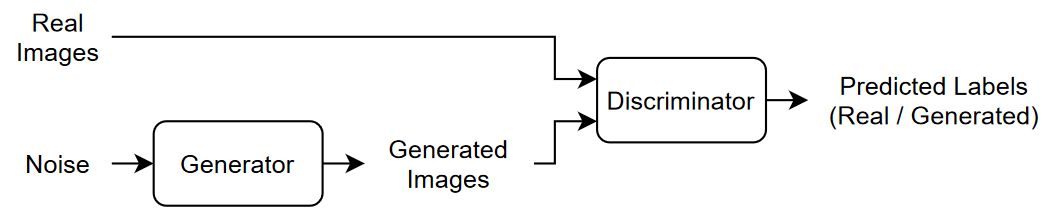

生成ネットワークと識別ネットワークはそれぞれ次のように学習します。

- 生成ネットワークは識別ネットワークを騙すように(本物だと間違えるように)学習します。

- 識別ネットワークは本物の画像と生成ネットワークから生成された画像を見分けるように学習します。

GANはこの二つのモデルを互いに学習することで互いに関係を持ち、学習を促すことにより高度な生成モデルになります。

今回はデジタル数字データセットであるMNISTを用いてGANを学習させます。

## 学習データの読み込み

[MNISTデータセット](https://paperswithcode.com/dataset/mnist)は一万枚のデジタル数字データセットです。0から9の番号があり通常は識別で使用されますが、今回は生成する画像として学習します。

[MNISTデータセット](https://paperswithcode.com/dataset/mnist)をダウンロードします。

clear;clc;close all force
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', 'nndatasets','DigitDataset');

データストアに画像を保存します。

imds = imageDatastore(digitDatasetPath,IncludeSubfolders=true);

MNISTの画像サイズは28×28ピクセルですが、学習をしやすくするため32×32ピクセルに変更します。

augmenter = imageDataAugmenter(RandXReflection=true);
augimds = augmentedImageDatastore([32 32],imds,DataAugmentation=augmenter);

## GANモデルの定義

GeneratorとDiscriminatorを定義します。

### Generatorの定義

今回のGeneratorは Noise_dim 次元のノイズベクトルから全結合層を用いてノイズマップに変換しています。

Noise_map_sizeは H×W×dim になっておりdimを変更することで精度が変化します。HとWは4に固定してください。

Noise mapに変換した後は3つのdeconvolution層によって32×32×1になります。

変更していい箇所は以下の部分です。

- 途中のConvolution層、活性化関数、バッチノーマライゼーション、などの追加、削除

- Convolution層のフィルタサイズや次元数の設定

モデルを変更する際の注意点は次のようになります。

- 出力サイズは32×32×1になるように調整すること

- 出力の最後の活性化関数はtanhであること

filterSize = 5;
numFilters = 64;
Noise_dim = 128;

Noise_map_size = [4 4 512];

layersGenerator = [
    featureInputLayer(Noise_dim)
    projectAndReshapeLayer(Noise_map_size)
    transposedConv2dLayer(filterSize,256)
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer(filterSize,128,Stride=2,Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer(filterSize,1,Stride=2,Cropping="same")
    tanhLayer];

netG = dlnetwork(layersGenerator);

### Discriminatorの定義

Discriminatorは本物の画像と生成された画像を識別するネットワークです。今回は32×32×1の数字画像を本物か偽物か識別するように学習します。

活性化関数は一般的にLeakyReluがいいとされていますが、データセットによって他の活性化関数がいい場合があります。

変更指定医箇所は以下の部分です。

- 各種パラメータ

- 途中のConvolution層、活性化関数、バッチノーマライゼーション、などの追加、削除

- Convolution層のフィルタサイズや次元数の設定

モデルを変更する際の注意点は次のようになります。

- 入力サイズは32×32×1なため、特徴マップの圧縮は最大で5回まで

- 出力の最後の次元数は1にし、活性化関数sigmoid関数を用いること

scale = 0.2;
dropoutProb = 0.5;
inputSize = [32 32 1];
filterSize = 5;

layersDiscriminator = [
    imageInputLayer(inputSize,Normalization="none")
    dropoutLayer(dropoutProb)
    convolution2dLayer(filterSize,64,Stride=2,Padding="same")
    leakyReluLayer(scale)
    convolution2dLayer(filterSize,128,Stride=2,Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer(filterSize,256,Stride=2,Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer(4,1)
    sigmoidLayer];

netD = dlnetwork(layersDiscriminator);

## 二回目以降の定義方法

二回目以降はディープラーニングネットワークデザイナーで編集可能です。

アプリからディープラーニングネットワークデザイナーを選び、ワークスペースからを選択。

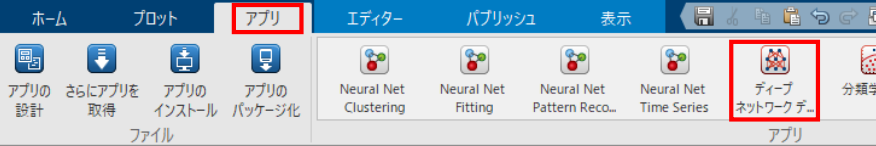

編集したいモデル(layersGeneratorかlayersDiscriminator)を選択し、OKボタンを押す。

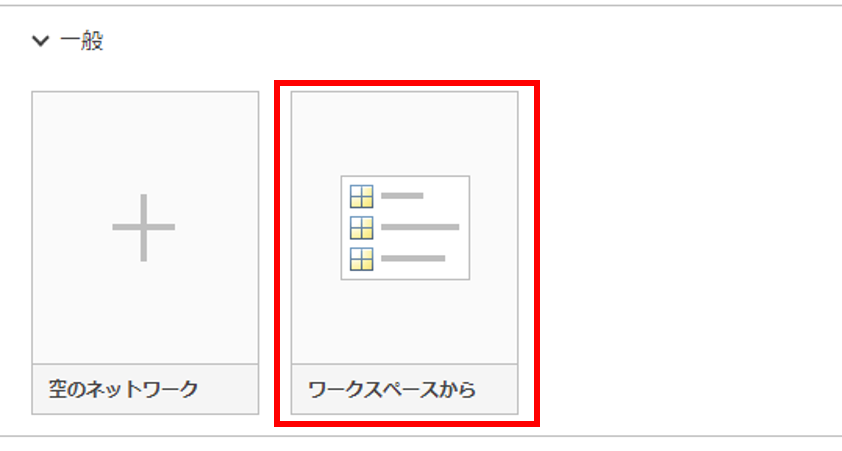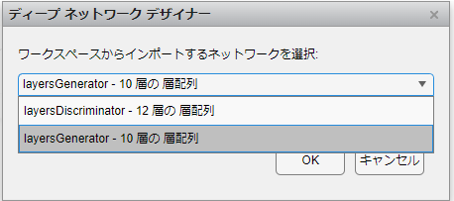

GeneratorやDiscriminatorの概要図は次のようになります。オレンジ色の部分は編集せずそれ以外の箇所を変更し性能を向上させましょう。

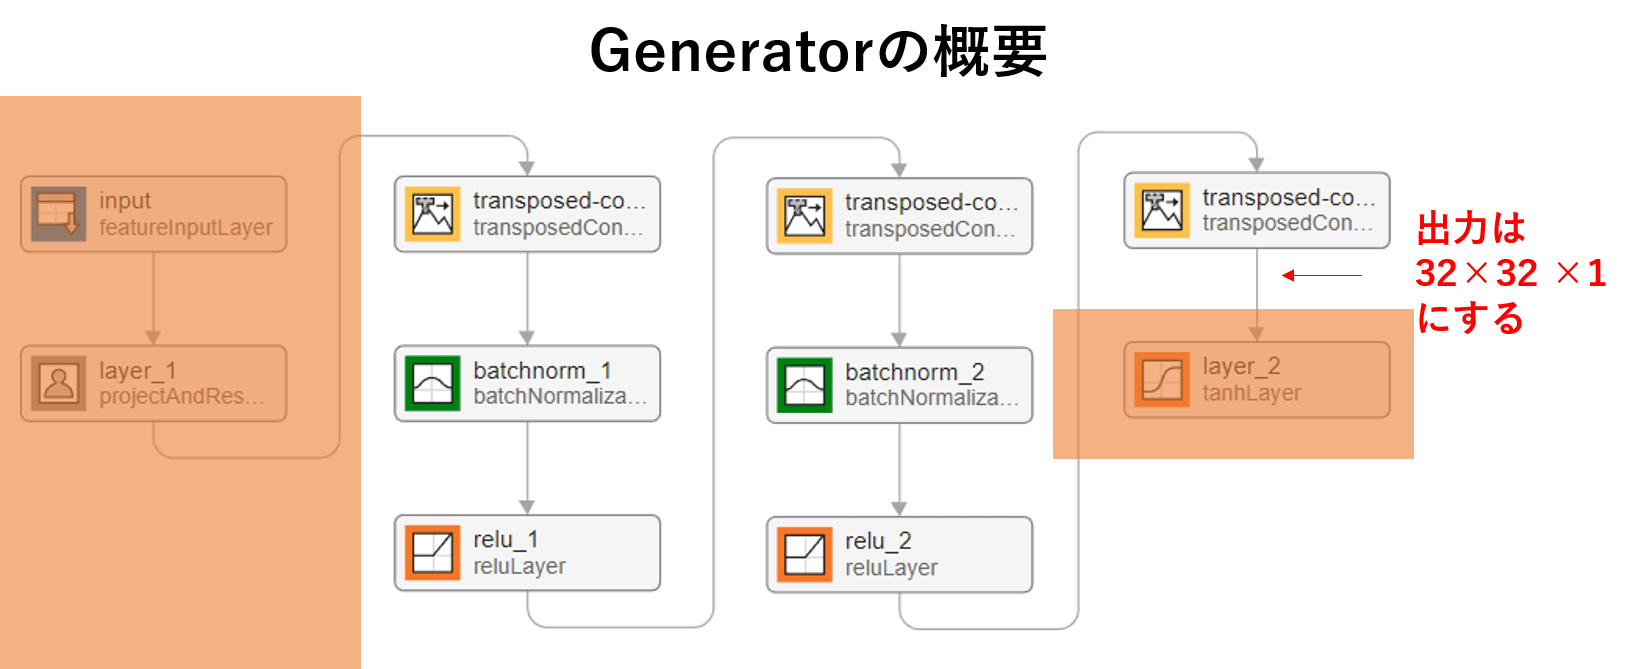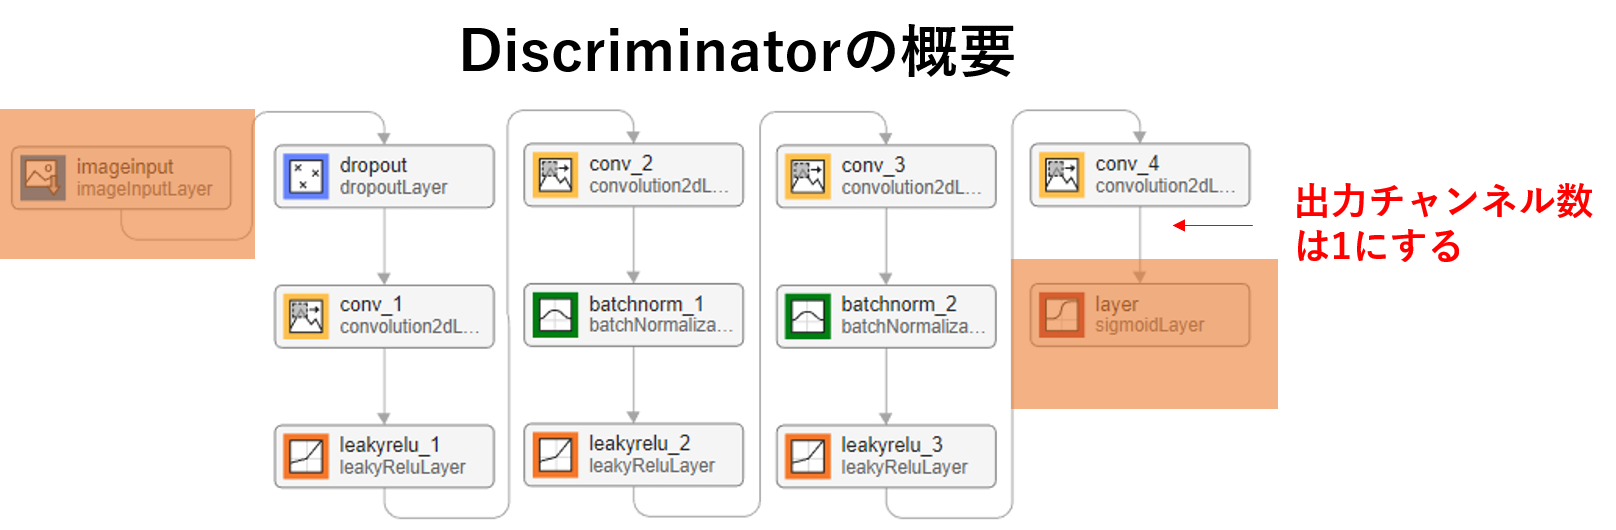

変更したら解析ボタンを押し、警告0、エラー2(デフォルトでエラーになります)ならばエクスポートボタンを押してください。

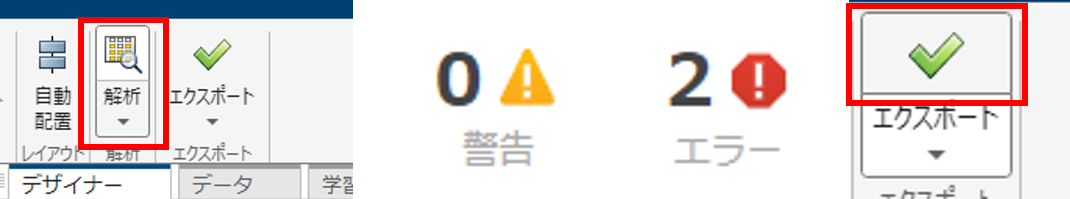

エクスポートが完了したら以下の画面が出てきます。layers_1などの名前は覚えておきましょう。

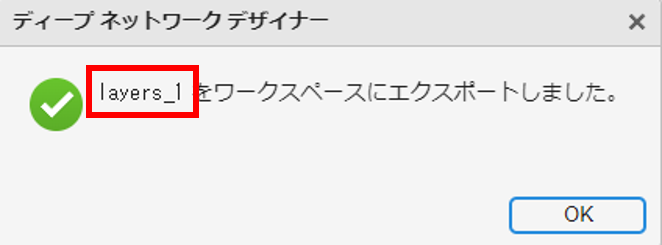

### Generatorの更新

エクスポートで出力されたモデル名を括弧の中にいれてください。(layers_1,layers_2など)

netG = dlnetwork(layers_1);

### Discriminatorの更新

エクスポートで出力されたモデル名を括弧の中にいれてください。(layers_1,layers_2など)

netD = dlnetwork(layers_2);

## 学習設定の定義

エポック数(学習回数)は5で固定にしましょう。バッチサイズは変更して精度を比較してみてください。

numEpochs = 5;
miniBatchSize = 128;

学習率や勾配減衰率を設定することができます。

学習率は小さければ小さいほど細かな学習ができますが、学習が進みにくくなります。適切に設定しましょう。

勾配減衰率(gradientDecayFactor)と二乗移動平均(squaredGradientDecayFactor)は調節が難しいため初期値で固定しましょう。

learnRate = 0.0002;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;

一般的にDiscriminatorはGeneratorよりも早く学習してしまいます。

するとDiscriminatorの損失が小さくなり勾配消失が発生しGeneratorの学習がうまく行かなくなります。

そこで本物の画像を左右反転させた画像を学習に用いることで識別器の学習を難しくし、学習バランスをとる手法があります。

flipProbは反転させる確率を示しており、高いほど反転する画像が多くなります。

ただし、今回は数字のデータであるため反転させたときに元とは違う分布(2や3が左右反転になると別の文字になる)になり、

うまく学習ができない可能性もあるため反転させないことも視野に入れてください。

反転確率flipProbは自由に設定してください。

flipProb = 0.35;

何回学習した時に画像を更新するかの値です。値が小さいほど細かく更新します。

validationFrequency = 20;

## モデルの学習

このセクションではモデルの学習を行います。

このセクションは実行するだけで生成された画像とグラフが表示されます。

青色のグラフがGeneratorのスコアで、オレンジ色がDiscriminatorのスコアです。

生成器のスコアは識別器を騙した割合を示しており、高いほどよい生成器であることを示しています。

識別器のスコアは与えられた画像が本物か偽物かを正しく判断した割合を示しており、高いほどよい識別機であることを示しています。

(生成器のスコアが100%になると識別器のスコアが0になるわけではありません。(実際の画像を正しく識別した場合があるため))

学習前設定のコード

augimds.MiniBatchSize = miniBatchSize;

mbq = minibatchqueue(augimds, ...
    MiniBatchSize=miniBatchSize, ...
    PartialMiniBatch="discard", ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB");

trailingAvgG = [];
trailingAvgSqG = [];
trailingAvg = [];
trailingAvgSqD = [];

numValidationImages = 25;
ZValidation = randn(Noise_dim,numValidationImages,"single");
ZValidation = dlarray(ZValidation,"CB");

f = figure;
f.Position(3) = 2*f.Position(3);

imageAxes = subplot(1,2,1);
scoreAxes = subplot(1,2,2);

C = colororder;
lineScoreG = animatedline(scoreAxes,Color=C(1,:));
lineScoreD = animatedline(scoreAxes,Color=C(2,:));
legend("Generator","Discriminator");
ylim([0 1])
xlabel("Iteration")
ylabel("Score")
grid on

学習には時間が掛かります。(テスト稼動では7分ほど)

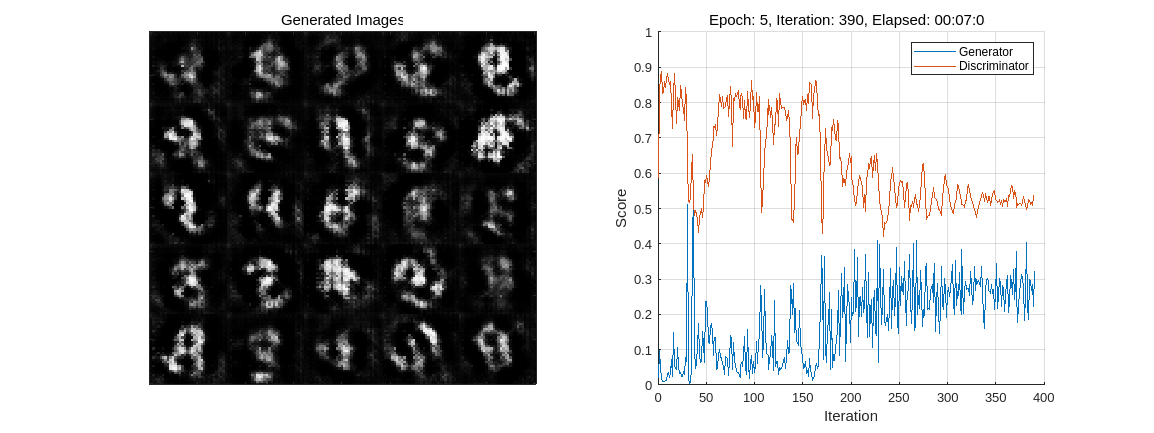

iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs

    % Reset and shuffle datastore.
    shuffle(mbq);

    % Loop over mini-batches.
    while hasdata(mbq)
        iteration = iteration + 1;

        % Read mini-batch of data.
        X = next(mbq);

        % Generate latent inputs for the generator network. Convert to
        % dlarray and specify the format "CB" (channel, batch). If a GPU is
        % available, then convert latent inputs to gpuArray.
        Z = randn(Noise_dim,miniBatchSize,"single");
        Z = dlarray(Z,"CB");

        if canUseGPU
            Z = gpuArray(Z);
        end

        % Evaluate the gradients of the loss with respect to the learnable
        % parameters, the generator state, and the network scores using
        % dlfeval and the modelLoss function.
        [~,~,gradientsG,gradientsD,stateG,scoreG,scoreD] = ...
            dlfeval(@modelLoss,netG,netD,X,Z,flipProb);
        netG.State = stateG;

        % Update the discriminator network parameters.
        [netD,trailingAvg,trailingAvgSqD] = adamupdate(netD, gradientsD, ...
            trailingAvg, trailingAvgSqD, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);

        % Update the generator network parameters.
        [netG,trailingAvgG,trailingAvgSqG] = adamupdate(netG, gradientsG, ...
            trailingAvgG, trailingAvgSqG, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);

        % Every validationFrequency iterations, display batch of generated
        % images using the held-out generator input.
        if mod(iteration,validationFrequency) == 0 || iteration == 1
            % Generate images using the held-out generator input.
            XGeneratedValidation = predict(netG,ZValidation);

            % Tile and rescale the images in the range [0 1].
            I = imtile(extractdata(XGeneratedValidation));
            I = rescale(I)*255;

            % Display the images.
            subplot(1,2,1);
            image(imageAxes,I)
            colormap(gray)
            xticklabels([]);
            yticklabels([]);
            title("Generated Images");
        end

        % Update the scores plot.
        subplot(1,2,2)
        scoreG = double(extractdata(scoreG));
        addpoints(lineScoreG,iteration,scoreG);

        scoreD = double(extractdata(scoreD));
        addpoints(lineScoreD,iteration,scoreD);

        % Update the title with training progress information.
        D = duration(0,0,toc(start),Format="hh:mm:ss");
        title(...
            "Epoch: " + epoch + ", " + ...
            "Iteration: " + iteration + ", " + ...
            "Elapsed: " + string(D))
        drawnow
    end
end
imwrite(frame2im(getframe(gcf)),"latest_result.png");

## 画像の生成

このセクションではノイズをランダムで選び、画像を生成できます。

このセクションを実行するたびに結果が変わるため様々な結果を比較して、明瞭な結果を保存しましょう。

numObservations = 25;
ZNew = randn(Noise_dim,numObservations,"single");
ZNew = dlarray(ZNew,"CB");

Generatorで画像を生成。

XGeneratedNew = predict(netG,ZNew);

画像の表示。画像を保存するには画像右上の矢印マークを押し、保存してください。

I = imtile(extractdata(XGeneratedNew));
I = rescale(I)*255;
figure
image(I)
colormap(gray)
axis off
title("Generated Images")

## GANの損失関数定義

以下は編集しないでください。

function [lossG,lossD,gradientsG,gradientsD,stateG,scoreG,scoreD] = ...
    modelLoss(netG,netD,X,Z,flipProb)

% Calculate the predictions for real data with the discriminator network.
YReal = forward(netD,X);

% Calculate the predictions for generated data with the discriminator
% network.
[XGenerated,stateG] = forward(netG,Z);
YGenerated = forward(netD,XGenerated);

% Calculate the score of the discriminator.
scoreD = (mean(YReal) + mean(1-YGenerated)) / 2;

% Calculate the score of the generator.
scoreG = mean(YGenerated);

% Randomly flip the labels of the real images.
numObservations = size(YReal,4);
idx = rand(1,numObservations) < flipProb;
YReal(:,:,:,idx) = 1 - YReal(:,:,:,idx);

% Calculate the GAN loss.
[lossG, lossD] = ganLoss(YReal,YGenerated);

% For each network, calculate the gradients with respect to the loss.
gradientsG = dlgradient(lossG,netG.Learnables,RetainData=true);
gradientsD = dlgradient(lossD,netD.Learnables);

end

## GAN Loss Function and Scores

The objective of the generator is to generate data that the discriminator classifies as `"real"`. To maximize the probability that images from the generator are classified as real by the discriminator, minimize the negative log likelihood function.

 Given the output $Y$ of the discriminator:

- $Y$ is the probability that the input image belongs to the class `"real"`.

- $1-Y$ is the probability that the input image belongs to the class `"generated"`.

The loss function for the generator is given by

    
$$\textrm{lossGenerator}=-\textrm{mean}\left(\log \left(Y_{\textrm{Generated}} \right)\right),$$


where $Y_{Generated}$ contains the discriminator output probabilities for the generated images. 

The objective of the discriminator is to not be "fooled" by the generator. To maximize the probability that the discriminator successfully discriminates between the real and generated images, minimize the sum of the corresponding negative log likelihood functions.

The loss function for the discriminator is given by

    
$$\textrm{lossDiscriminator}=-\textrm{mean}\left(\log \left(Y_{\textrm{Real}} \right)\right)-\textrm{mean}\left(\log \left(1-Y_{\textrm{Generated}} \right)\right),$$


where $Y_{Real}$ contains the discriminator output probabilities for the real images. 

To measure on a scale from 0 to 1 how well the generator and discriminator achieve their respective goals, you can use the concept of score. 

The generator score is the average of the probabilities corresponding to the discriminator output for the generated images:

    
$$\textrm{scoreGenerator}=\textrm{mean}\left(Y_{\textrm{Generated}} \right)\ldotp$$


The discriminator score is the average of the probabilities corresponding to the discriminator output for both the real and generated images:

    
$$\mathrm{scoreDiscriminator}=\frac{1}{2}\mathrm{mean}\left(Y_{\mathrm{Real}} \;\right)+\frac{1}{2}\mathrm{mean}\left(1-Y_{\mathrm{Generated}} \right)\ldotp$$


The score is inversely proportional to the loss but effectively contains the same information.

function [lossG,lossD] = ganLoss(YReal,YGenerated)

% Calculate the loss for the discriminator network.
%lossD = -mean(log(YReal)) - mean(log(1-YGenerated));
lossD = mean((1 - YReal).^2) + mean(YGenerated.^2);

% Calculate the loss for the generator network.
%lossG = -mean(log(YGenerated));
lossG = mean((1 - YGenerated).^2);

end

## Mini-Batch Preprocessing Function

The `preprocessMiniBatch` function preprocesses the data using the following steps:

- Extract the image data from the incoming cell array and concatenate into a numeric array.

- Rescale the images to be in the range `[-1,1]`. 

function X = preprocessMiniBatch(data)

% Concatenate mini-batch
X = cat(4,data{:});

% Rescale the images in the range [-1 1].
X = rescale(X,-1,1,InputMin=0,InputMax=255);

end

## References

- Radford, Alec, Luke Metz, and Soumith Chintala. “Unsupervised Representation Learning with Deep Convolutional Generative Adversarial Networks.” Preprint, submitted November 19, 2015. http://arxiv.org/abs/1511.06434.